# Heart Disease

Train classification models on patient data to predict heart disease diagnosis.

#### Import and Prepare Data

Load the example data and extract numerical predictors.

heartData = readtable("heartDiseaseData.csv");
heartData = convertvars(heartData,12:22,"categorical");
heartDataNum = heartData(:,[1:11 22]);

Partition into training and test sets.

rng(1234)
pt = cvpartition(heartData.HeartDisease,"Holdout",0.2);
hdTrainNum = heartDataNum(training(pt),:);
hdTestNum = heartDataNum(~training(pt),:);
hdTrain = heartData(training(pt),:);
hdTest = heartData(~training(pt),:);

## kNN Classification

mdl = fitcknn(hdTrainNum,"HeartDisease");
resubLoss(mdl)

ans = 0

loss(mdl,hdTestNum)

ans = 0.3413

Visualize prediction accuracy.

HDpred = predict(mdl,hdTestNum);
HDtrue = hdTestNum.HeartDisease;
[cm,grp] = confusionmat(HDtrue,HDpred)

cm =     19    19
    10    37


grp = 2×1 categorical array
     false 
     true 


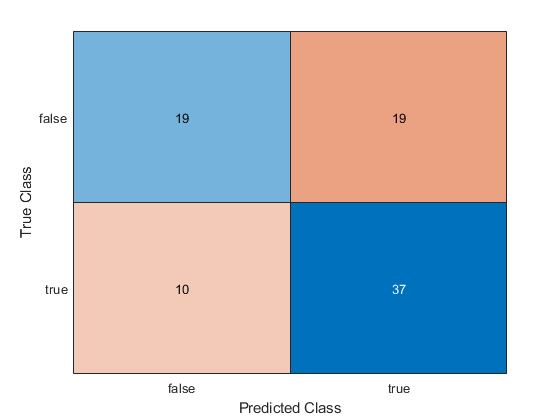

confusionchart(HDtrue,HDpred);

Increase the number of neighbors.

mdl.NumNeighbors = 5;
resubLoss(mdl)

ans = 0.2222

loss(mdl,hdTestNum)

ans = 0.2471

Change the distance weighting option.

mdl.DistanceWeight = "squaredinverse";
resubLoss(mdl)

ans = 0

loss(mdl,hdTestNum)

ans = 0.2471

## Decision Trees

Fit and evaluate a decision tree model with default settings.

mdl = fitctree(hdTrainNum,"HeartDisease");
resubLoss(mdl)

ans = 0.0789

loss(mdl,hdTestNum)

ans = 0.2706

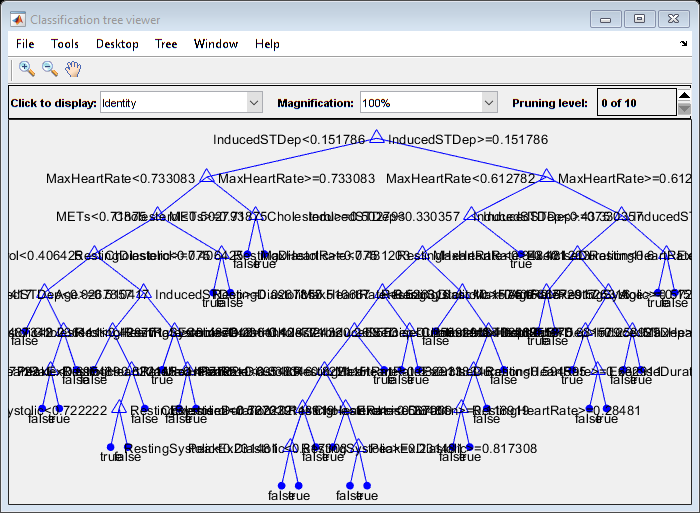

view(mdl,"mode","graph")

Prune the tree.

mdl = prune(mdl,"Level",3);
resubLoss(mdl)

ans = 0.1404

loss(mdl,hdTestNum)

ans = 0.1883

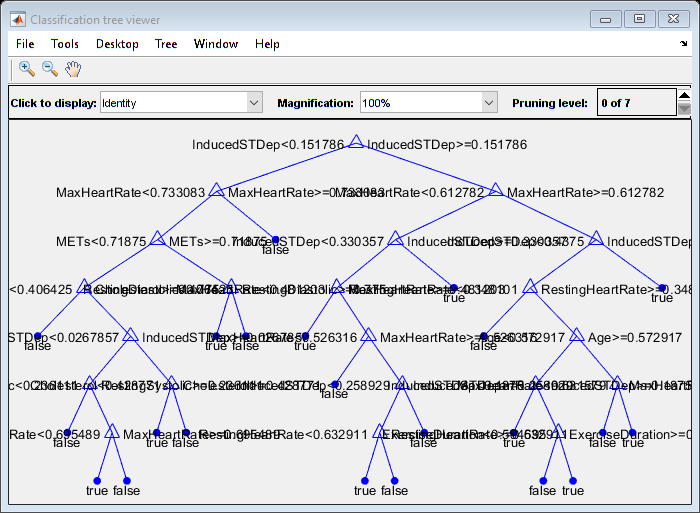

view(mdl,"mode","graph")

Use a mix of numeric and categorical predictors.

mdl = fitctree(hdTrain,"HeartDisease");
resubLoss(mdl)

ans = 0.0526

loss(mdl,hdTest)

ans = 0.2471

mdl = prune(mdl,"Level",3);
resubLoss(mdl)

ans = 0.0994

loss(mdl,hdTest)

ans = 0.2118

## Naive Bayes

Fit and evaluate a Naive Bayes model with default settings.

mdl = fitcnb(hdTrainNum,"HeartDisease");
resubLoss(mdl)

ans = 0.2982

loss(mdl,hdTestNum)

ans = 0.2000

Use kernel smoothing instead of normal distributions.

mdl = fitcnb(hdTrainNum,"HeartDisease","DistributionNames","kernel");
resubLoss(mdl)

ans = 0.2602

loss(mdl,hdTestNum)

ans = 0.1765

Use a mix of numeric and categorical predictors.

mdl = fitcnb(hdTrain,"HeartDisease");
resubLoss(mdl)

ans = 0.2047

loss(mdl,hdTest)

ans = 0.1177

Use kernel smoothing instead of normal distributions.

dists = [repmat("kernel",1,11) repmat("mvmn",1,10)];
mdl = fitcnb(hdTrain,"HeartDisease","DistributionNames",dists);
resubLoss(mdl)

ans = 0.1959

loss(mdl,hdTest)

ans = 0.1412

## Discriminant Analysis

Fit and evaluate a linear discriminant model with default settings.

mdl = fitcdiscr(hdTrainNum,"HeartDisease");
resubLoss(mdl)

ans = 0.2719

loss(mdl,hdTestNum)

ans = 0.1765

Use a quadratic boundary.

mdl = fitcdiscr(hdTrainNum,"HeartDisease","DiscrimType","quadratic");
resubLoss(mdl)

ans = 0.2485

loss(mdl,hdTestNum)

ans = 0.2706

## SVM

Fit and evaluate an SVM with default settings.

mdl = fitcsvm(hdTrainNum,"HeartDisease");
resubLoss(mdl)

ans = 0.3012

loss(mdl,hdTestNum)

ans = 0.1647

Use a nonlinear kernel. 

mdl = fitcsvm(hdTrainNum,"HeartDisease","KernelFunction","gaussian");
resubLoss(mdl)

ans = 0.2602

loss(mdl,hdTestNum)

ans = 0.1647

Use a mix of numeric and categorical predictors.

mdl = fitcsvm(hdTrain,"HeartDisease");
resubLoss(mdl)

ans = 0.1901

loss(mdl,hdTest)

ans = 0.1530

Use a nonlinear kernel.

mdl = fitcsvm(hdTrain,"HeartDisease","KernelFunction","gaussian");
resubLoss(mdl)

ans = 0.0409

loss(mdl,hdTest)

ans = 0.1765

## Multiclass SVM

Load and partition multiclass heart disease data set.

heartDataMulti = readtable("heartDiseaseDataMulticlass.csv");
heartDataMulti = convertvars(heartDataMulti,12:22,"categorical");
hdMTrain = heartDataMulti(training(pt),:);
hdMTest = heartDataMulti(~training(pt),:);
hdMTrainNum = heartDataMulti(training(pt),[1:11 22]);
hdMTestNum = heartDataMulti(~training(pt),[1:11 22]);

Linear SVM

mdl = fitcecoc(hdMTrainNum,"HeartDisease");
linResubLoss = resubLoss(mdl)

linResubLoss = 0.5058

linTestLoss = loss(mdl,hdMTestNum)

linTestLoss = 0.5002

Gaussian SVM

template = templateSVM("KernelFunction","gaussian");
mdl = fitcecoc(hdMTrainNum,"HeartDisease","Learners",template);
gaussResubLoss = resubLoss(mdl)

gaussResubLoss = 0.4591

gaussTestLoss = loss(mdl,hdMTestNum)

gaussTestLoss = 0.4893

Linear SVM with mixed predictors

mdl = fitcecoc(hdMTrain,"HeartDisease");
mixedLinResubLoss = resubLoss(mdl)

mixedLinResubLoss = 0.4064

mixedLinTestLoss = loss(mdl,hdMTest)

mixedLinTestLoss = 0.5442

Gaussian SVM with mixed predictors

template = templateSVM("KernelFunction","gaussian");
mdl = fitcecoc(hdMTrain,"HeartDisease","Learners",template);
mixedGaussResubLoss = resubLoss(mdl)

mixedGaussResubLoss = 0.1520

mixedGaussTestLoss = loss(mdl,hdMTest)

mixedGaussTestLoss = 0.5064